# ACM 11: Week 6 Exercise 2 - Higher-order Newton-Cotes

**(0) Names of group members: Kyle McGraw**

In this demo/activity: we consider piecewise polynomial interpolation of the following function:

$f(x)=\frac{1}{1+25x^2}$,

using varying orders of polynomial interpolation over equispaced points, as is Newton-Cotes integration. In the code below, we divide the interval into 12 spaces and 13 points, which can be considered as 12 subintervals with 2 points each, 6 subintervals with 3 points each, 4 subintervals with 4 points each, 3 subintervals with 5 points each, or 2 subintervals with 7 points each, or 1 subinterval with 13 points. We do a piecewise-polynomial interpolation within each subinterval and add the integral of that polynomial to the integrand (I cheated and did not actually derive the higher-order Newton-Cotes weights; we are just using MATLAB's integral command on the polynomial interpolant, which is what the Newton-Cotes weights basically do).

**(1) As a group, discuss and convince yourselves that the code below does indeed do what is described in the text above. You may want to use the MATLAB help function to look up **`vander` **and** `polyval`.

**Convinced.**

**(2) Using the drop down menu, vary the order of the piecewise polynomial used for Newton-Cotes integration. What is surprising about the highest-order interpolant?**

**We see it go negative on the ends.**

**(3) Does the error of the Newton-Cotes integral approximation always decrease as its order is increased? Why or why not?**

**Error does not always decrease as its order is increased because of Runge's Phenomenon.**

% function to be integrated
f = @(x) 1./(1+25*x.^2);

% bounds
a = -1; b = 1; 

% exact integral for comparison
exact =  integral(f,a,b)

exact = 0.5494


N = 12;

% order of lagrange interpolation
p = 12;

x = linspace(a,b,N+1);

% plotting on a fine grid
xplt = linspace(a,b,200);
figure(1); clf
plot(xplt,f(xplt),'k'); hold on
plot(x,f(x),'ro')
xlabel('x')
ylabel('f(x)')

nc_approx = 0;
for i = 1:N/p   % loop through sub-intervals
    xint = x(p*(i-1)+1:p*i+1);          % get points in the current subinterval
    pcoeff = vander(xint)\f(xint');     % solve for polynomial interpolant

    xx = linspace(xint(1),xint(end),100);
    plot(xx,polyval(pcoeff,xx),'r:')
    plot([x(p*(i-1)+1) x(p*(i-1)+1)],[0, f(x(p*(i-1)+1))],'k:')
    nc_approx = nc_approx + integral(@(x) polyval(pcoeff,x),xint(1),xint(end));
end
plot([x(N+1) x(N+1)],[0, f(x(N+1))],'k:')
grid on

err = exact - nc_approx

err = 0.6119

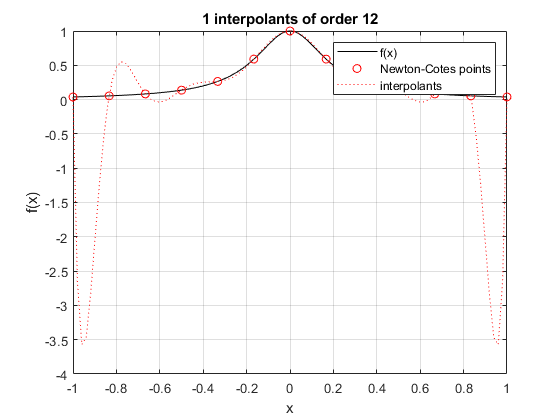


xlabel('x')
legend('f(x)','Newton-Cotes points','interpolants')
title([num2str(N/p) ,' interpolants of order ',num2str(p)])